% 0.1
clc; clear; close all;
syms u

y = 3*sin(u)

$$y = 3\,\sin\left(u\right)$$


fprintf('y for different input values u.')

y for different input values u.

for c = 1:10
    result = double(subs(y, u, c));
    fprintf('y(%d) = 3 * sin(%d) -> %.4f\n', c, c, result);  % Print formatted output
end

y(1) = 3 * sin(1) -> 2.5244
y(2) = 3 * sin(2) -> 2.7279
y(3) = 3 * sin(3) -> 0.4234
y(4) = 3 * sin(4) -> -2.2704
y(5) = 3 * sin(5) -> -2.8768
y(6) = 3 * sin(6) -> -0.8382
y(7) = 3 * sin(7) -> 1.9710
y(8) = 3 * sin(8) -> 2.9681
y(9) = 3 * sin(9) -> 1.2364
y(10) = 3 * sin(10) -> -1.6321


% 0.2

fprintf('Values of y for an interval of u ∈ [0, 2π].')

Values of y for an interval of u ∈ [0, 2π].

for c = 1:0.1:2*pi
    result = double(subs(y, u, c));
    fprintf('y(%.2f) = 3 * sin(%.2f) -> %.4f\n', c, c, result);  % Print formatted output
end

y(1.00) = 3 * sin(1.00) -> 2.5244
y(1.10) = 3 * sin(1.10) -> 2.6736
y(1.20) = 3 * sin(1.20) -> 2.7961
y(1.30) = 3 * sin(1.30) -> 2.8907
y(1.40) = 3 * sin(1.40) -> 2.9563
y(1.50) = 3 * sin(1.50) -> 2.9925
y(1.60) = 3 * sin(1.60) -> 2.9987
y(1.70) = 3 * sin(1.70) -> 2.9750
y(1.80) = 3 * sin(1.80) -> 2.9215
y(1.90) = 3 * sin(1.90) -> 2.8389
y(2.00) = 3 * sin(2.00) -> 2.7279
y(2.10) = 3 * sin(2.10) -> 2.5896
y(2.20) = 3 * sin(2.20) -> 2.4255
y(2.30) = 3 * sin(2.30) -> 2.2371
y(2.40) = 3 * sin(2.40) -> 2.0264
y(2.50) = 3 * sin(2.50) -> 1.7954
y(2.60) = 3 * sin(2.60) -> 1.5465
y(2.70) = 3 * sin(2.70) -> 1.2821
y(2.80) = 3 * sin(2.80) -> 1.0050
y(2.90) = 3 * sin(2.90) -> 0.7177
y(3.00) = 3 * sin(3.00) -> 0.4234
y(3.10) = 3 * sin(3.10) -> 0.1247
y(3.20) = 3 * sin(3.20) -> -0.1751
y(3.30) = 3 * sin(3.30) -> -0.4732
y(3.40) = 3 * sin(3.40) -> -0.7666
y(3.50) = 3 * sin(3.50) -> -1.0523
y(3.60) = 3 * sin(3.60) -> -1.3276
y(3.70) = 3 * sin(3.70) -> -1.5895
y(3.80) = 3 * sin(3.80) -> -1.8356
y(3.90)

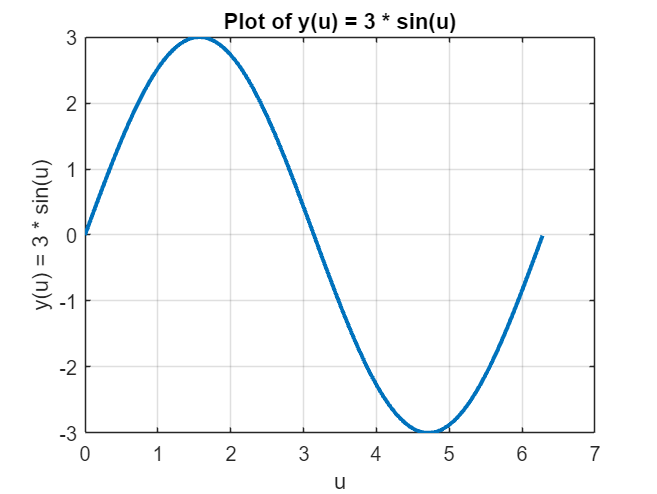


% Plot y(u) for u from 0 to 2*pi
u_plot = 0:0.01:2*pi;  % Finer resolution for the plot
y_plot = double(subs(y, u, u_plot));

figure;
plot(u_plot, y_plot, 'LineWidth', 2);
xlabel('u');
ylabel('y(u) = 3 * sin(u)');
title('Plot of y(u) = 3 * sin(u)');
grid on;

% 0.3

fprintf('rotated vector w')

rotated vector w

v = transpose([1, 2])

v =      1
     2



syms theta
R = [cos(theta), -sin(theta);
     sin(theta), cos(theta)]

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$


R = subs(R, theta, 2*pi/3)

$$R = \left(\begin{array}{cc} -\frac{1}{2} & -\frac{\sqrt{3}}{2}\\ \frac{\sqrt{3}}{2} & -\frac{1}{2} \end{array}\right)$$


w = R*v

$$w = \left(\begin{array}{c} -\sqrt{3}-\frac{1}{2}\\ \frac{\sqrt{3}}{2}-1 \end{array}\right)$$